f = @(t,y) [y(1)^2+y(2)^2-1; y(1) - y(2)];
df = @(t,y) [2*y(1),2*y(2);1,-1];
ti = 0;
h = 1;
yi = [2;0];
x0 = [2;0];

tol = 10^(-8);
nmax = 100;

[x,y,exitflag] = newton(@(zi) F_euler(zi,ti,h,yi,f,df),x0,tol,nmax)

x =   -0.369729031991648
   0.815135484004176


y =    2.691958318405258
                   0


exitflag =      0



[x,y,exitflag] = newton(@f_beispiel,x0,tol,nmax)

x =    0.707106781186547
   0.707106781186547


y = 	1.0e+-15 *

  -0.222044604925031
                   0


exitflag =      1



$$y^{\left(i\right)} \approx y\left(\mathrm{ti}\right)$$


tspan = [0,1]

tspan =      0     1


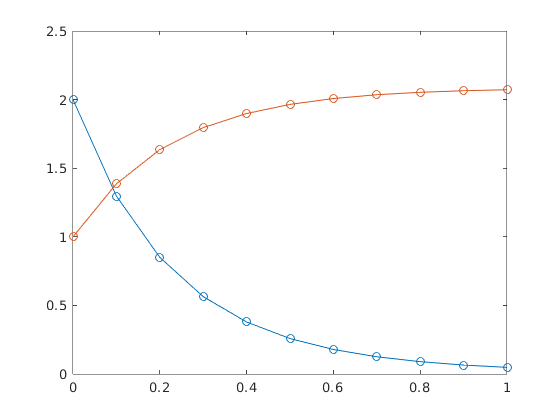

n = 10;
ya = [2;1];
tol = 10^(-15);
nmax = 100;
f = @(t,y) [t*y(1)-3*y(2);3*y(1)-((t^2)*y(2))];
df = @(t,y) [t,-3;3,-(t^2)];
[t,y_out] = impl_euler(f,tspan,ya,n,df,tol,nmax);
plot(t,y_out, '-o')

function [f,df] = f_beispiel(y)
    f = [y(1)^2+y(2)^2-1; y(1) - y(2)];
    df = [2*y(1),2*y(2);1,-1];
end